**Data Cleaning exercise:**

Data Scientists and Analysts are often tasked to clean and analyze datasets. We are working with an external research firm who specializes in the application of artificial intelligence to forecasting prices of financial instruments. This firm has developed a proprietary system, called “4sight”, to forecast prices of certain instruments.

To demonstrate the effectiveness of their forecasting system, the vendor has sent us attached sample dataset. The dataset includes signal values generated by the 4sight system as well as historical prices for a well-known broad market ETF. 

A Portfolio Manager has asked you to:

1)      Review the quality of the data, list any potential errors, and propose corrected values. Please list each quality check error and correction applied.

2)      Please analyze the signal’s effectiveness or lack thereof in forecasting ETF price, using whatever metrics you think are most relevant.

3)      (Extra credit) Write a 1-2 paragraph summary for the Portfolio Manager addressing your observations about the efficacy and believability of the product, and recommendation for next steps.

Please budget at least one hour for completing this exercise. Please include all the intermediate steps when sending your solution to this exercise back to us.

**Step 1) Review the quality of the data, list any potential errors, and propose corrected values. Please list each quality check error and correction applied.**

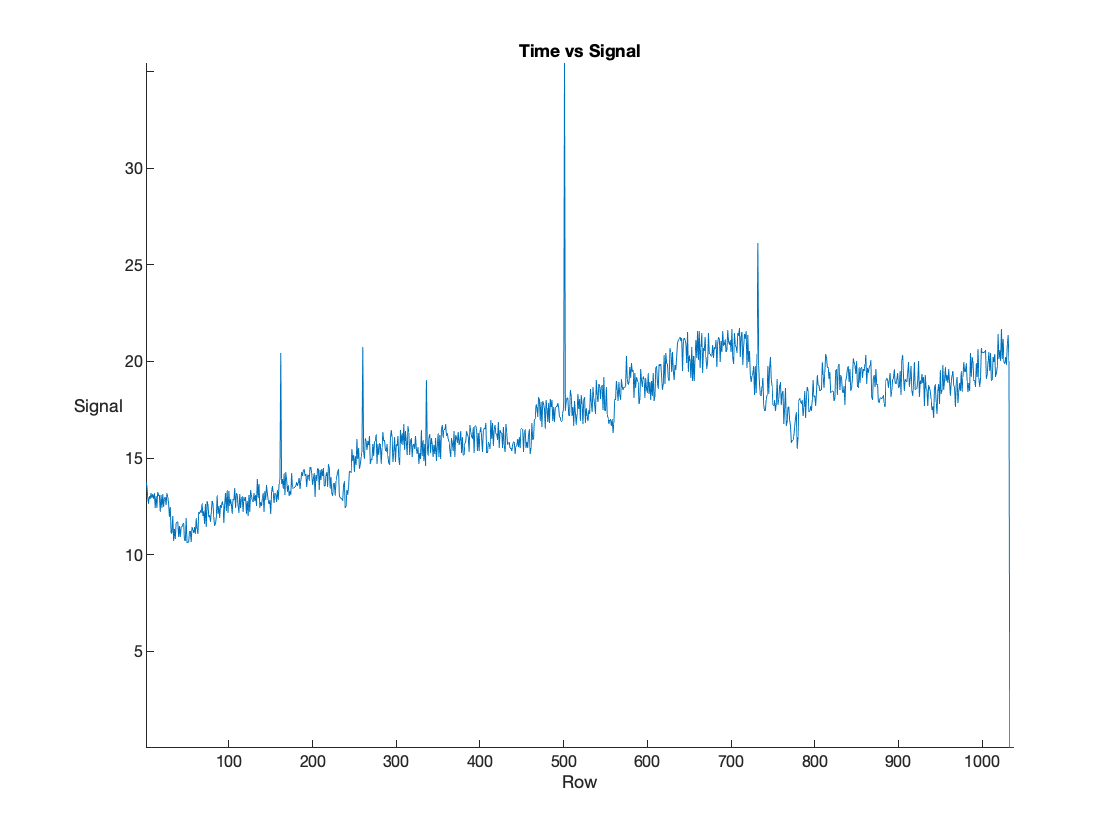

%% import data manually
stackedplot(SampleDataset(:,2))
title('Time vs Signal')

 signalOutlierIDXS = find(isoutlier(SampleDataset(:,2), 'movmedian', 120))

signalOutlierIDXS =          162
         260
         336
         501
         732
        1033
        1034
        1035
        1036
        1037


There are a number of outliers in the signal data which are potentially indicitive of errors in the source data that was used to generate the prediction. However, the signal from t=1033 through t=1038 are 0 while all other columns are present so these values are simply missing. This could be an inherent issue with the prediction sofftware that may be worth 

let's poke around to find out where the errors at indices [260, 336, 501, 732] are coming from:

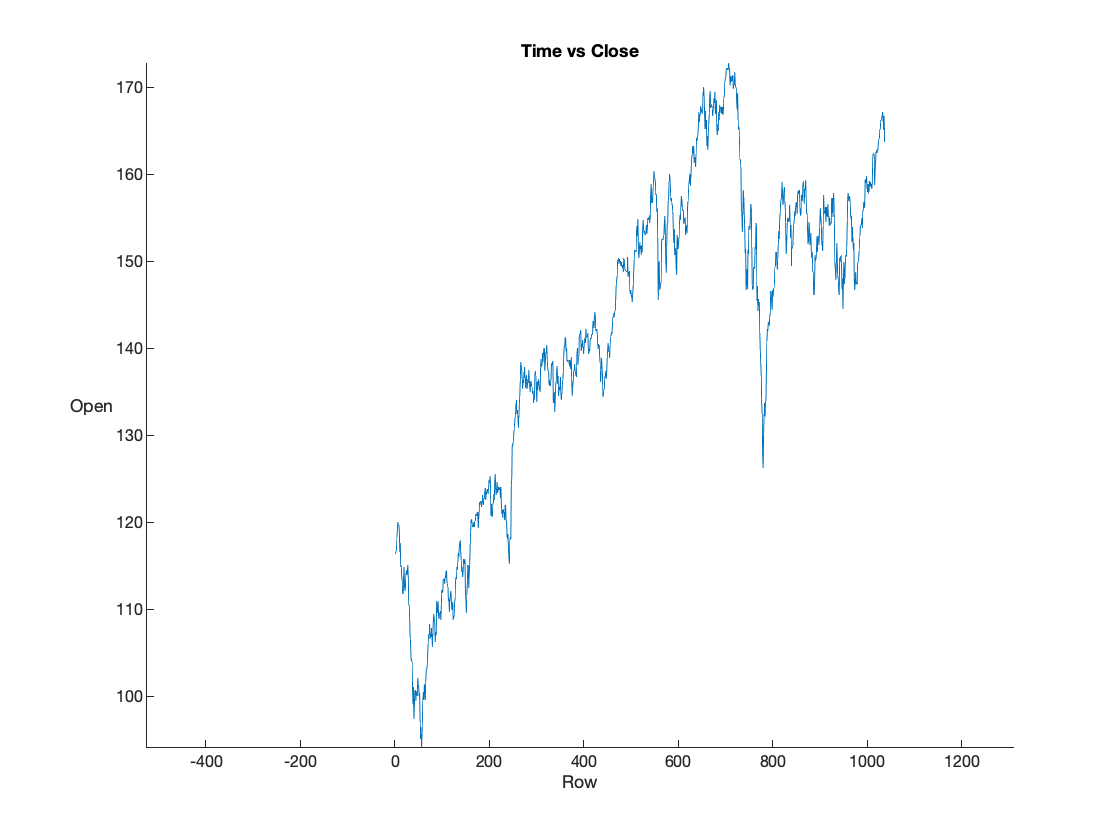

stackedplot(SampleDataset(:,3))
title('Time vs Close')

closeOutlierIDXS = find(isoutlier(SampleDataset(:,3), 'movmedian', 120))

closeOutlierIDXS =    779
   780
   781
